# Digital Image Processing Assignment 1

## Student Name & Z Number: Meghananjali Remala, Z23701551

## Table of Contents

## 1. Reading and Displaying Original Image

## 2. Selecting Image Processing Filter

## 3. Applying the Chosen Filter

## 4. Displaying Result Image

## 5. Saving Result Image

## 6. Hosting code on GitHub

## Title:Image Processing Filter

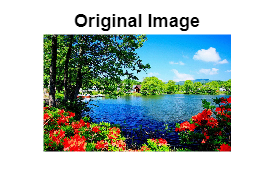

%% reading a creative image
creativeImgPath = 'DIP Assignment 1/Image.jpg';  
originalImg = imread(creativeImgPath);

%% displaying the original image
figure('Name', 'Original Image');
imshow(originalImg);
title('Original Image');

## Using a LiveScript control-questdlg

## The user is prompted by this MATLAB code to select an image processing filter between "Custom Filter" and "Grayscale." If 'Grayscale' is selected, rgb2gray is used to convert the original image to grayscale; if not, imcomplement is used to apply a custom filter by inverting the colors.

% selecting filter to be applied
filterChoice = questdlg('Select an Image Processing Filter:', 'Filter Select', 'Grayscale', 'Custom Filter', 'Grayscale');
if strcmp(filterChoice, 'Grayscale')
    processedImg = rgb2gray(originalImg);
else
    % Custom Filter: Invert Colors
    processedImg = imcomplement(originalImg);
end


## Displaying the Result

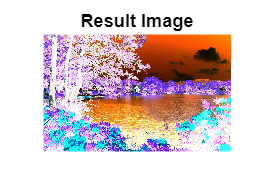

%% displaying the result image
figure('Name', 'Result Image');
imshow(processedImg);
title('Result Image');

## Saving the Result in .png file

%% saving the resulting image
imwrite(processedImg, 'DIP Assignment 1/result_Image.png');
disp('Result image saved as result_Image.png');

Result image saved as result_Image.png


## Hosting code on GitHub

## link: https://meghananjaliremala.github.io/ImageProcessingMatlab/